clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


## Design Procedure 1

param.ctrl.Ks = control.DesignProcedure1(param,0);

Evaluation of design procedure 1 
Q is positive definite


ans =     0.3021    0.3034    0.3034    0.3034    0.7871    0.7871    0.7871    0.7884    2.0153    2.0153    2.0153    2.0161


R is positive definite


ans = 1.0e+03 *

    0.0292    0.0401    0.0462    0.1149    0.2445    0.2718    0.2776    0.2900    0.3183    0.3541    0.4120    1.0937


Gamma is found to be:


ans = 119.1575

Eigenvalues of the decoupled systems are all negative 


ans =   -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2415 + 4.0904i  -1.2415 - 4.0904i  -0.2806 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i  -1.2382 + 4.0460i  -1.2382 - 4.0460i  -0.2810 + 0.0000i


Eigenvalues of the coupled systems are all negative 


ans =   -0.7633 + 5.6104i  -0.7633 - 5.6104i  -0.4591 + 6.3840i  -0.4591 - 6.3840i  -0.3645 + 6.6218i  -0.3645 - 6.6218i  -0.3397 + 6.6635i  -0.3397 - 6.6635i  -0.2748 + 0.0000i  -0.2731 + 0.0000i  -0.2726 + 0.0000i  -0.2727 + 0.0000i


0.000000, -9.161631, -9.161631, -9.161631, 
0.000000, 0.000000, 0.000000, -12.964306, 
0.000000, 0.000000, 0.000000, -1.994579, 


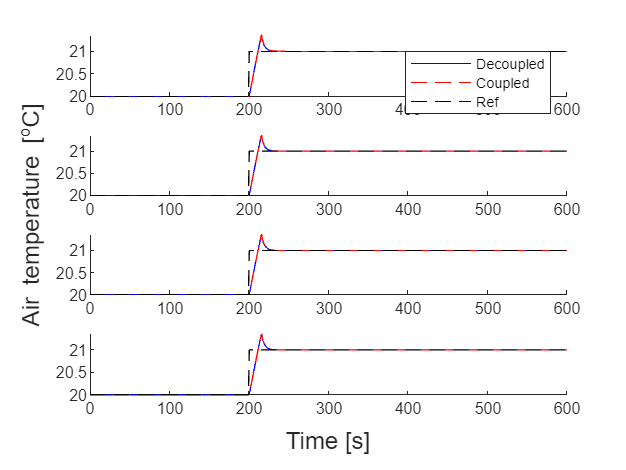

util.SimulateStep(param,"Examination_Baseline_DP1",0);

## Design procedure 2

param.ctrl.Ks = control.DesignProcedure2(param,0,1);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0015    0.0015    0.0015    0.0016    0.1684    0.1689    0.1693    0.1695    4.1608    4.6637    4.7502    4.8541


Gamma is found to be:


ans = 1

Eigenvalues of the decoupled systems are all negative 


ans =    -4.0059   -0.0311   -0.0000   -4.0442   -0.0312   -0.0000   -4.0059   -0.0311   -0.0000   -4.0058   -0.0311   -0.0000


Eigenvalues of the coupled systems are all negative 


ans =    -4.0442   -4.0059   -4.0059   -4.0058   -0.0311   -0.0312   -0.0311   -0.0311   -0.0000   -0.0000   -0.0000   -0.0000


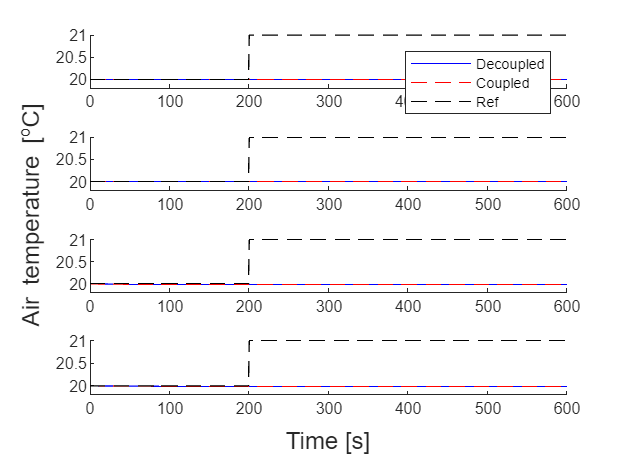

util.SimulateStep(param,"Examination_Baseline_DP2",1);